## アニメーション

GIF に出力するためのスクリプトです。

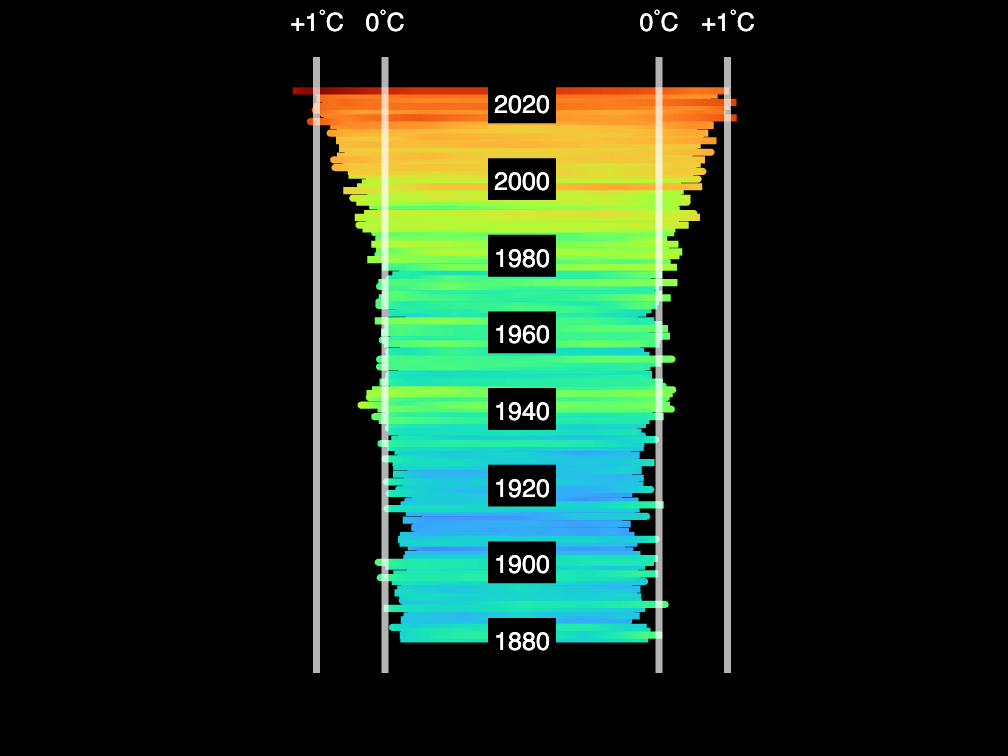

filename = 'temperature.gif';

handle_fig = figure;
[handle_fig, handle_axes, handle_year] = setUpFigure(handle_fig);
hold on

colors = colormap('turbo'); % 256x3 (1 が 1.1, 256 が 3.5 に対応)
colorFnc = @(t) floor((t - 1.1)/((3.5-1.1)/255) + 1); % 入力：気温、出力：色（1~256）

h = surf(handle_axes, [xm(1:2) xm(1:2)], [ym(1:2) ym(1:2)], ...
    [zm(1:2) zm(1:2)], [radiusm(1:2) radiusm(1:2)], ...  % Reshape and replicate data
    FaceColor = 'none', ...    % Don't bother filling faces with color
    EdgeColor = 'interp', ...  % Use interpolated color for edges
    LineWidth = 4);            % Make a thicker line
axis equal off

frame = getframe(handle_fig); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
tmp = frame2im(frame); % 画像に変更
[A,map] = rgb2ind(tmp,256); % RGB -> インデックス画像に
imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',0.2);

% Adding dataset.
for idx=3:length(xm)

    % yearm(idx)
    h.XData = repmat(xm(1:idx),1,2);
    h.YData = repmat(ym(1:idx),1,2);
    h.ZData = repmat(zm(1:idx),1,2);
    h.CData = repmat(radiusm(1:idx),1,2);

    ha.XLim = [-4.5,4.5];
    ha.YLim = [-4.5,4.5];
    ha.ZLim = [-4.5,4.5];

    handle_year.String = yearm(idx);
    handle_year.Color = colors(colorFnc(radiusm(idx)),:);

    if ~mod(idx,63) % factor(length(xm)) = [3,3,7,137];
        drawnow % グラフアップデート

        frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
        tmp = frame2im(frame); % 画像に変更
        [A,map] = rgb2ind(tmp,256); % RGB -> インデックス画像に
        % 画像をアペンド
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.05);
    end
end

imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1);

handles2delete = findobj(Tag='delete');
delete(handles2delete)

frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
tmp = frame2im(frame); % 画像に変更
[A,map] = rgb2ind(tmp,256); % RGB -> インデックス画像に
% 画像をアペンド
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1);

% Rotate view
for ii=1:90
    rotate(h,[1,0,0],-1); % x 軸周りに回転

    if ~mod(ii,3) % update graphics semi-annually
        drawnow

        frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
        tmp = frame2im(frame); % 画像に変更
        [A,map] = rgb2ind(tmp,256); % RGB -> インデックス画像に
        % 画像をアペンド
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.1);
    end
end

xline(2, Color = 'white', LineWidth = 4) % x = 2 (0 度）
xline(-2, Color = 'white', LineWidth = 4) % x = 2 (0 度）
xline(3, Color = 'white', LineWidth = 4) % x = 2 (+1 度）
xline(-3, Color = 'white', LineWidth = 4) % x = 2 (+1 度）

% Property の設定項目が多いかつ共通なので、こんな形で文字数減らします。
propSet = {"Color",[1,1,1],'HorizontalAlignment','center','VerticalAlignment','middle',...
    'BackgroundColor','k','Interpreter','tex','FontSize',14};
text(2,5,0,"0^\circC",propSet{:});
text(-2,5,0,"0^\circC",propSet{:});
text(3,5,0,"+1^\circC",propSet{:});
text(-3,5,0,"+1^\circC",propSet{:});


frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
tmp = frame2im(frame); % 画像に変更
[A,map] = rgb2ind(tmp,256); % RGB -> インデックス画像に
% 画像をアペンド
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1);

y2disp = 1880:20:2020;
idx = ismember(year,y2disp);

yeardata = unique(year(idx));
zdata = unique(z(idx));

for ii=1:length(yeardata)
    text(0,zdata(ii),4,string(yeardata(ii)),propSet{:},...
        FontSize = 16);
end

frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ

tmp = frame2im(frame); % 画像に変更
[A,map] = rgb2ind(tmp,256); % RGB -> インデックス画像に
% 画像をアペンド
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1);
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',2);